# Examen RA3L - Matlab Partie 2

% Nom :   sab                                    /10
% Prénom : 23027
% Matricule : ADDA

Le fichier Data_note.mat contient l'enregistrement d'un son produit par un instrument de musique. Le but principal de ce questionnaire est de déterminer à quelle note de musique (et à quelle octave) la fréquence fondamentale du son correspond. Pour ce faire, nous utiliserons l'analyse fréquentielle de la note enregistrée pour la comparer avec le tableau des fréquences des notes de musique ci-dessous. 

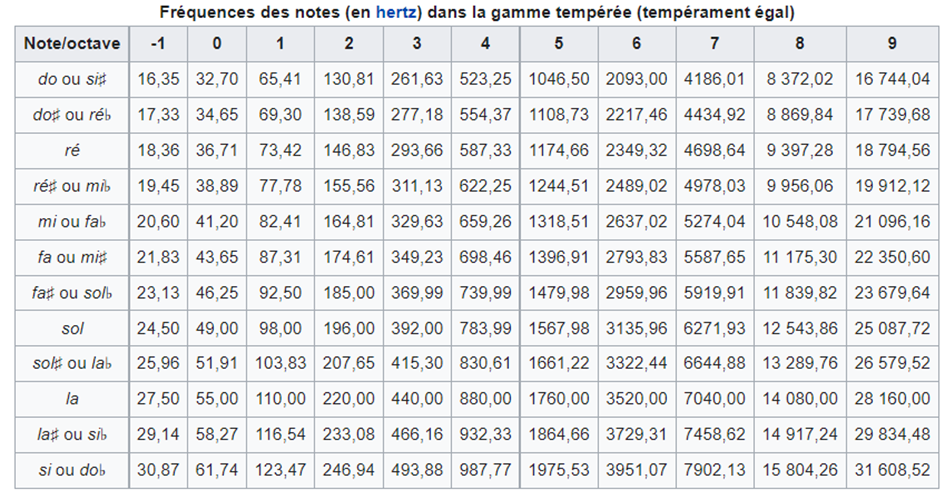

Source : Wikipedia

**1) Charger les données et visualiser le son joué en fonction du temps. Déterminer ensuite la fréquence (Fs) et la période d'échantillonage (Ts). *****(0.5 point)***

clear all
close all
load('data_note.mat')

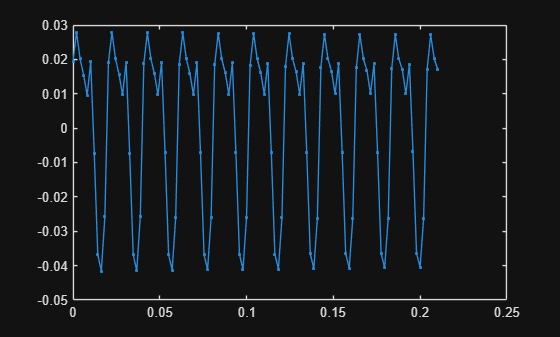

%code
Ts=mode(diff(t));
fs=1/Ts;
plot(t,u,'.-')

Résultat attendu :

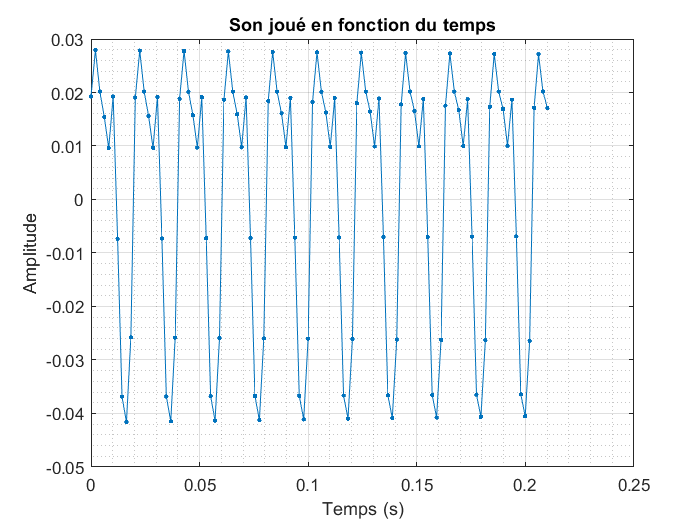

**2) Corriger le code fourni permettant d'appliquer la FFT sur le signal en justifiant les corrections exécutées ****sur feuille annexe****. *****(2 points)***. 

Voici le code fourni à corriger :  

*        N=length(t)*

        *X=fft(u);*

*        Amp=abs(X);*

*        Amp=Amp(1:N/2);*

*        n=1:1:N;*

*        dF=N*Ts;*

*        f=n*dF;*

*        stem(f,Amp)*

Implémenter le code corrigé pour appliquer la FFT et visualiser le contenu fréquentiel du signal fourni. ***(1 point)***. 


%code
N=length(t)

N = 104

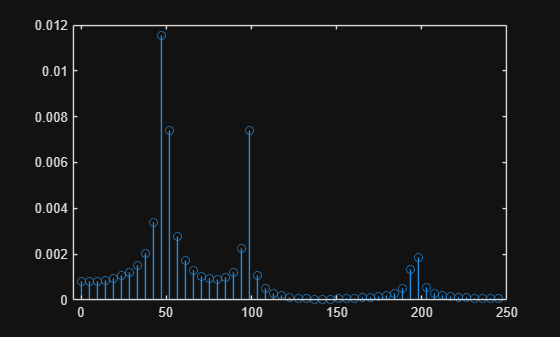

X=fft(u);
Amp=abs(X)/N;
Amp=Amp(1:N/2+1);
n=0:1:N/2;
dF=1/N/Ts;
f=n*dF;
stem(f,Amp)

Résultat attendu : 

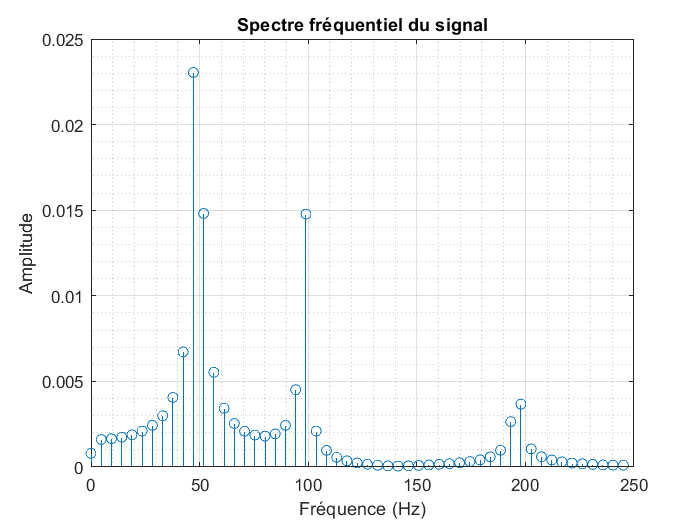

**3) Le spectre obtenu à la question 2 est-il correct ? Justifier, ****sur feuille annexe****, avec du texte et/ou avec un/des schémas. (2 *****points*****)**

**nyquist est respecté car 200*2<490->2*fmax<fs**

**fenetre bonne ? n*ts=m*T? t(end)/T=m is m integer pas besoin, je le vois sur le graphe car la derniere periode se finit pas donc on a mal fenetré**

**4) Appliquer les corrections nécessaires (ou pas) pour implémenter à nouveau la FFT sur le signal et visualiser le spectre fréquentiel du son joué. (0.5***** point*****)**

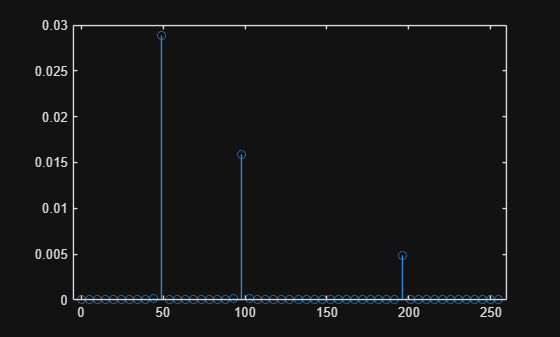

%code
%1 période =10 points et moi j'ai un peu plus de 10 periodes donc je prends
%que les 100 premiers points
N1=100;
X1=fft(u(1:100));
ampx=abs(X1)/N;

ampx=ampx(1:N/2+1)*2;
ampx(1)=ampx(1)/2;

df=fs/100;
n=0:1:N/2;

f=n*df;
stem(f,ampx)

Résultat attendu :

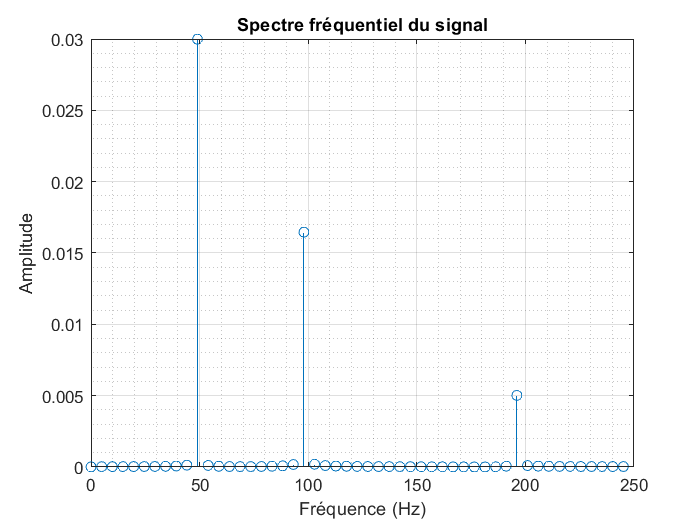

En regardant l'amplitude dominante (la plus grande) sur le graphe obtenu et via le tableau mentionné ci-dessus, quelle note est jouée et à quelle octave ? (Ce n'est pas obligatoire d'utiliser Matlab pour cette question). 

%code facultatif %c'est du sol car sol on a moins de 50 moins de 100 et moins de 200  

**5)** Le son joué comprend, outre la note fondamentale, 3 harmoniques qui correspondent à la même note aux 3 octaves supérieures successives. Par exemple, si la note était un ré à l'octave 5, ces harmoniques correspondraient à des rés aux octaves 6, 7 et 8.

**Indiquer, ****sur feuille annexe****, les rangs de ces 3 harmoniques. Le spectre obtenu à la question 4 est-il correct ? Justifier avec du texte et/ou avec un/des schémas. (*****1 point*****)**

**SOL octave 0 c'est la fondamentale donc c'est harmonique je vais regatder octave 1 2 3 et c'est harmonique 2 4 8 . NON LE SPECTRE NEST PAS CORRECT CAR IL MANQUE LHARMONIQUE 8, ON AURAIT DU AVOIR UNE FREQUENCE D ECHANTILLONNAGE D AU MOINS 780HZ**

**6) **On aimerait attenuer les octaves supérieures du son joué. **Appliquer un filtre passe-bas au signal d'entrée dont la fréquence de coupure **$\omega_{c\;}$** permet de réduire les fréquences supérieures à 200 Hz (**$\omega_{c\;} =2\pi *200$** rad/s) avec un un coefficient d'amortissement **$\xi$ à 0.8 ($\left.\xi =0\ldotp 8\right)$**. **


$$H\left(s\right)=\frac{1}{\left(\frac{s^2 }{\omega_c^2 \;}+\frac{2s\xi }{\omega {\;}_c }+1\right)}$$


**Afficher le signal de sortie **(à stocker dans la variable y)** et le signal d'entrée de ce filtre sur le même graphique. (1***** point*****)**

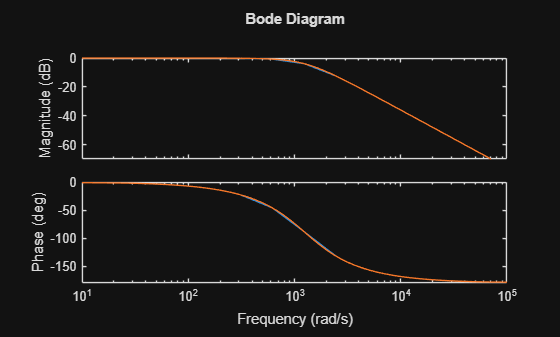

%code
s=tf('s');
wc=400*pi;
xi=0.8;
H=1/((s^2/wc^2)+(2*s*xi/wc)+1);
y=lsim(H,u,t);
plot(t,u,t,y);

Résultat attendu :

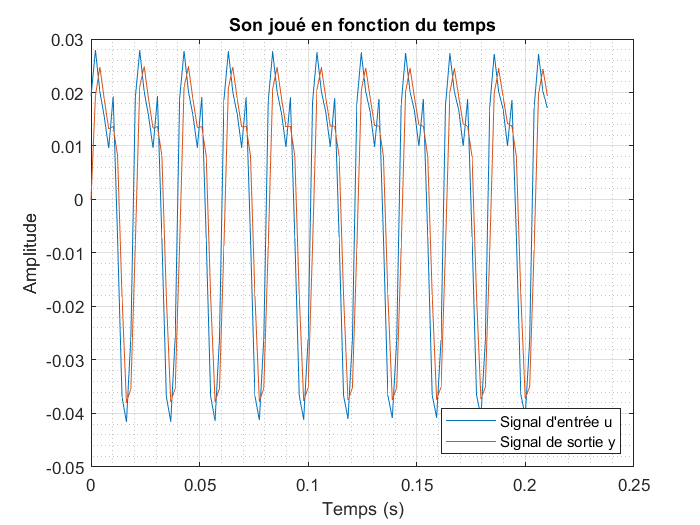

**7) Afficher**, sur le même graphique, **le diagramme de Bode du filtre passe-bas ainsi que les fréquences pour lesquelles le système a été sollicité. (*****1 point*****)**

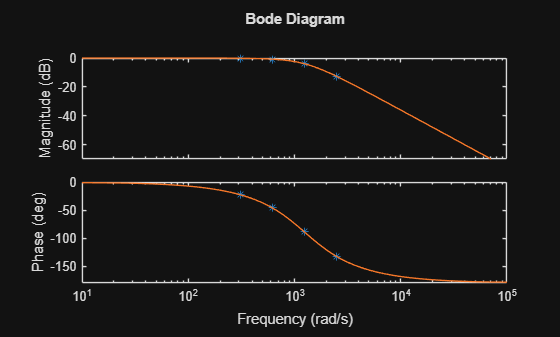

%code
clf;
wspe=[49 98 196 392]*2*pi;
bode(H,wspe,'*');
hold on
bode(H);

Résultat attendu :

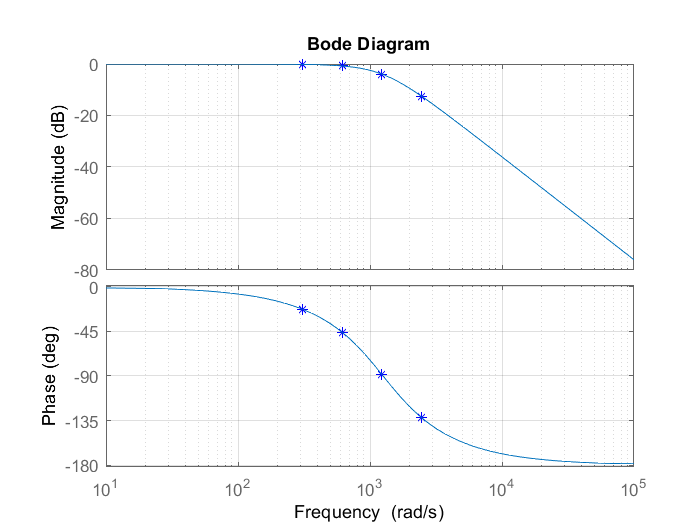

**8) ****Sur feuille annexe****, expliquer pourquoi il y a un décalage temporel entre l'entrée et la sortie du filtre sur base des résultats obtenus aux questions 6 et 7. (*****1 point*****)**

NB : il est conseillé d'utiliser Matlab pour vous aider à répondre à cette question sur papier. 

%code facultatif